# Phase Vocoding Demo

#### Fourier Transform Settings

% Frame & Hop Size
N = 128;
HOP_SIZE = N/8;

H = HOP_SIZE / N; % HOP_FACTOR

% Windowing
% WINDOW = ones(N, 1);
WINDOW = kaiser(N, 4);

% Fourier transform
FFT = dsp.FFT();
IFFT = dsp.IFFT();

#### Pitch-Shift Settings

% Synthesized Frame & Hop Size
M = N*2;
HOP_SIZE_M = M * H;
WINDOW_M = kaiser(M, 4);

PITCH_SHIFT_FACTOR = M / N; 

% Phase locking (CAN and WILL be changed)
FIND_PHASE_LOCK_BINS = @valleyPhaseLock;

#### Graph Settings

% Colors
PEAK_BIN_COLOR = [0.522 0.086 0.820];
MUTUAL_PEAK_BIN_COLOR = [1 0 0];
ESTIMATED_FREQUENCIES_COLOR = [0.231 0.667 0.196];

#### Signal Definition

% Signal Length (Best if in incremements of HOP_SIZE)
SIGNAL_LENGTH = HOP_SIZE*30;

% All frequency terms (ω, Φ, A)
FREQUENCIES = [
    9.8/N,0,1;
];

% The signal is the sum of multiple complex sinusoidal terms
x = @(t) ... % Signal
    sum(exp(1j * (2 * pi * FREQUENCIES(:, 1) * t + FREQUENCIES(:, 2))) .* FREQUENCIES(:, 3), 1);

TOTAL_FRAMES = floor(( SIGNAL_LENGTH - N ) / HOP_SIZE);

# Pitch-Shifting Code

#### Loop Over The Entire Signal

% Initialization
prevPeaks = [];
prevPhaseSpec = zeros(N, 1);
prevPhaseSpec_Modulated = zeros(M, 1);

outputtedSignal = zeros(SIGNAL_LENGTH / N * M, 1); 

% GRAPHING PURPOSES
% Initialize plots for the figures
frameNum = 1;

sampledSignalPlots = gobjects(TOTAL_FRAMES, 1);
windowedSignalPlots = gobjects(TOTAL_FRAMES, 1);
ampSpecPlot = gobjects(TOTAL_FRAMES, 4);
interpolatedAmpSpecPlot = gobjects(TOTAL_FRAMES, 1);
synthesizedFramePlot = gobjects(TOTAL_FRAMES, 2);

% Update
for n = 0 : HOP_SIZE : TOTAL_FRAMES * HOP_SIZE

% Body

#### Sampling and Preprocessing

% Sample the signal at t = n
x_sampled = x( n:(n + N-1) )'; % Samples frames n to n + N - 1

% Window the sampled signal
x_windowed = x_sampled .* WINDOW;


% GRAPHING PURPOSES
% Graph the sampled and windowed
figure(1);
sampledSignalPlots(frameNum) = plot(0:N-1, real(x_sampled)', Color="b");
hold on;

figure(2);
windowedSignalPlots(frameNum) = plot(0:N-1, real(x_windowed)', Color="b");
hold on;

#### Short-Time-Fourier-Transform

% STFT is implicit
X = FFT( conj( x_windowed ) ); % Turn into the conjugate so that it transforms properly

% Convert to polar spectrum
X_polar = convertToPolar( X );


% GRAPHING PURPOSES
% Graph the amplitude spectrum
figure(3);
ampSpecPlot(frameNum, 1) = stem(0:N-1, real(X_polar(:, 1))', Color="blue", Marker="none");
hold on;

#### Estimate Frequencies

% Find the current and mutual peaks
currentPeaks = findPeaks( X_polar(:, 1) );
mutualPeaks = intersect(prevPeaks, currentPeaks);

peakFrequencies = currentPeaks - 1; % Make a list of the frequencies that peak

% Get the phases of the corresponding mutual peaks and calculate phase difference
phaseDifferences = X_polar(mutualPeaks, 2) - prevPhaseSpec(mutualPeaks);

% Calculate frequency deviation and add to the frequency bins
% (mutualPeaks-1) gets the frequency of the mutual peak bins
frequencyDeviations = wrap( phaseDifferences/2/pi/H - (mutualPeaks-1) , 1/H );
estimatedFrequencies = (mutualPeaks-1) + frequencyDeviations;

% Set the mutual peaks to their new estimated frequencies
peakFrequencies(ismember(peakFrequencies, mutualPeaks-1)) = estimatedFrequencies;


% GRAPHING PURPOSES
% Graph peaks and estimated frequency
figure(3);
ampSpecPlot(frameNum, 2:4) = [
    stem(currentPeaks-1, X_polar(currentPeaks, 1), Color=PEAK_BIN_COLOR, Marker="x"), ...
    stem(mutualPeaks-1, X_polar(mutualPeaks, 1), Color=MUTUAL_PEAK_BIN_COLOR, Marker="x"), ...
    stem(estimatedFrequencies, estimatedFrequencies * 0, Color=ESTIMATED_FREQUENCIES_COLOR, Marker="|", LineWidth=2) ...
];

#### Modulate Spectrum

% Interpolate Spectrum (Linear interpolation of amplitude and phase spectrum)
X_polar_interpolated = interpolateSpectrum(X_polar, N, M);

% Scale the peak frequencies to the interpolated spectrum
peakFrequencies = peakFrequencies / N * M;

% Create the spectrum of modulated values
modulatedSpec = X_polar_interpolated;

if n ~= 0
% Iterate through all the frequency spectrums
    for peakFrequency = peakFrequencies'
        
        % Find the corresponding peaking bin
        peakBin = round(peakFrequency) + 1;
    
        % Calculate the phase correction
        phaseCorrection = ( ...
                    prevPhaseSpec_Modulated(peakBin) ...
                    + 2 * pi * H * peakFrequency ...
                ) - modulatedSpec(peakBin, 2);
    
        % Adjust the phase
        phaseLockRange = FIND_PHASE_LOCK_BINS(peakBin, modulatedSpec(:, 1));
        modulatedSpec(phaseLockRange(1):phaseLockRange(2), 2) = modulatedSpec(phaseLockRange(1):phaseLockRange(2), 2) + phaseCorrection;
    end
end

% GRAPHING PURPOSES
figure(4);
interpolatedAmpSpecPlot(frameNum) = stem(0:M-1, X_polar_interpolated(:, 1)', Color="g", Marker="none");
hold on;

#### Resynthesize the Spectrum

% Resynthesize
Y = IFFT( convertToComplex( modulatedSpec ) );
Y = conj( Y );

% Y = Y ./ [WINDOW; WINDOW];

% Properly scale the frame
Y = Y / 2; % I'm too lazy to calculate the actual scale factor

% Overlap add the result
n_M = n / HOP_SIZE * HOP_SIZE_M;
outputtedSignal((n_M + 1):(n_M + M)) = outputtedSignal((n_M + 1):(n_M + M)) + Y;

% GRAPHING PURPOSES
figure(5);
synthesizedFramePlot(frameNum, 1) = plot(real(Y)', "blue");
hold on;
synthesizedFramePlot(frameNum, 2) = plot(real(x_windowed)', "red");

#### Update and End The Loop

% Update the previous spectrum information
prevPeaks = currentPeaks;
prevPhaseSpec = X_polar(:, 2);
prevPhaseSpec_Modulated = modulatedSpec(:, 2);

% Increment frame number
frameNum = frameNum + 1;

end

figure(6);
plot(real(outputtedSignal)', "blue");
hold on;
plot(real(x(0:SIGNAL_LENGTH))', "red");
hold off;

ylim([-10, 10]);

#### Label the figures

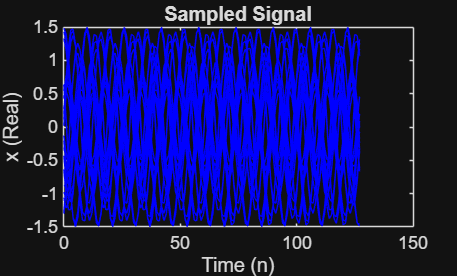

%% labelFigure does hold off automatically
labelFigure(1, "Sampled Signal", "Time (n)", "x (Real)");

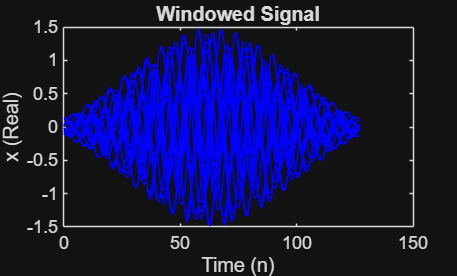

labelFigure(2, "Windowed Signal", "Time (n)", "x (Real)");

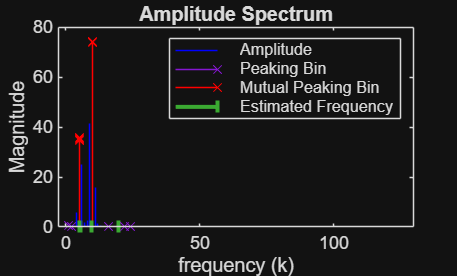

labelFigure(3, "Amplitude Spectrum", "frequency (k)", "Magnitude"); legend({"Amplitude", "Peaking Bin", "Mutual Peaking Bin", "Estimated Frequency"});

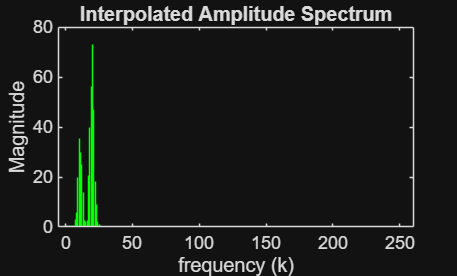

labelFigure(4, "Interpolated Amplitude Spectrum", "frequency (k)", "Magnitude");

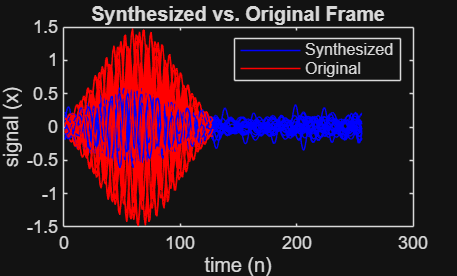

labelFigure(5, "Synthesized vs. Original Frame", "time (n)", "signal (x)"); legend({"Synthesized", "Original"});

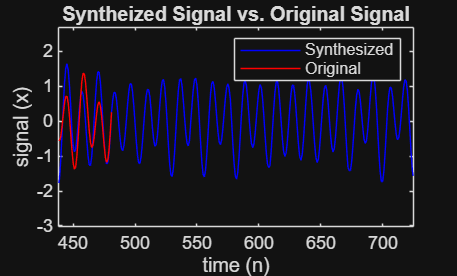

labelFigure(6, "Syntheized Signal vs. Original Signal", "time (n)", "signal (x)"); legend({"Synthesized", "Original"});

# Graph Controls

 
selectedFrame = 5

selectedFrame = 5

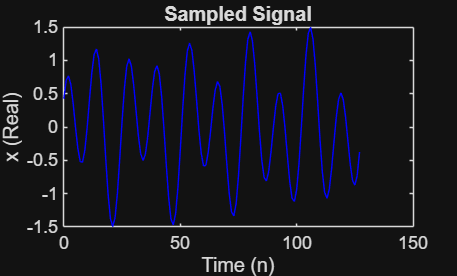

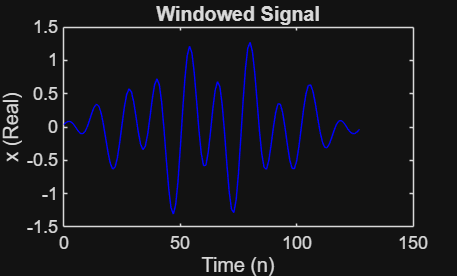

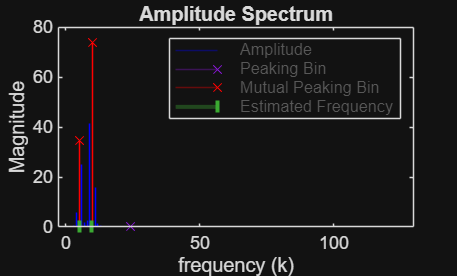

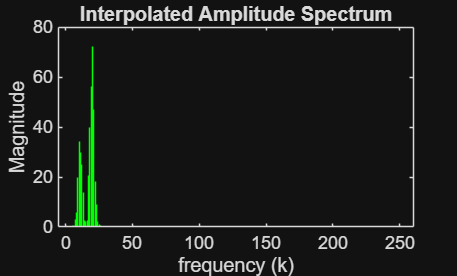

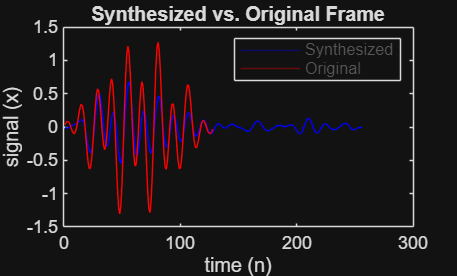

selectFrameData(selectedFrame, [ ...
    sampledSignalPlots, ... 
    windowedSignalPlots, ...
    ampSpecPlot, ...
    interpolatedAmpSpecPlot, ...
    synthesizedFramePlot, ...
]);